clear
U=100; % В
X_C=20; % Ом
R=80; % Ом
X_L=60; % Ом
Ud=U;

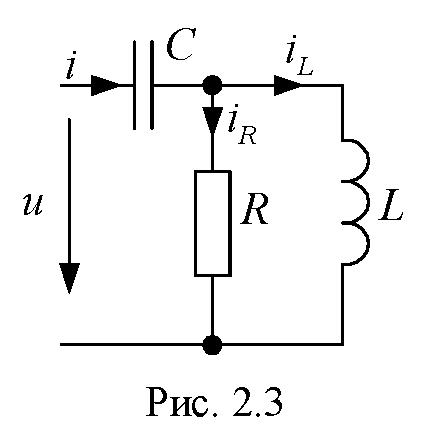

Комплексные сопротивления

Z1=-1j*X_C, Z2=R, Z3=1j*X_L

Z1 = 0.0000 - 20.0000i

Z2 = 80

Z3 = 0.0000 + 60.0000i

Z23=vpa(Z2*Z3/(Z2+Z3)), Zp23=vpa([abs(Z23),angle(Z23)*180/pi])

$$Z23 = 28.8+38.4\,\mathrm{i}$$

$$Zp23 = \left(\begin{array}{cc} 48.0 & 53.13 \end{array}\right)$$

Z=vpa(Z1+Z23), Zp=vpa([abs(Z),angle(Z)*180/pi])

$$Z = 28.8+18.4\,\mathrm{i}$$

$$Zp = \left(\begin{array}{cc} 34.18 & 32.57 \end{array}\right)$$

Ток на входе цепи

Id=vpa(Ud/Z), Ip=vpa([abs(Id),angle(Id)*180/pi])

$$Id = 2.466-1.575\,\mathrm{i}$$

$$Ip = \left(\begin{array}{cc} 2.926 & -32.57 \end{array}\right)$$

Напряжение на участке 2-3

Ud23=vpa(Id*Z23), Up23=vpa([abs(Ud23),angle(Ud23)*180/pi])

$$Ud23 = 131.5+49.32\,\mathrm{i}$$

$$Up23 = \left(\begin{array}{cc} 140.4 & 20.56 \end{array}\right)$$

Токи ветвей

Id_R=vpa(Ud23/Z2), Ip_R=vpa([abs(Id_R),angle(Id_R)*180/pi])

$$Id\_R = 1.644+0.6164\,\mathrm{i}$$

$$Ip\_R = \left(\begin{array}{cc} 1.756 & 20.56 \end{array}\right)$$

Id_L=vpa(Ud23/Z3), Ip_L=vpa([abs(Id_L),angle(Id_L)*180/pi])

$$Id\_L = 0.8219-2.192\,\mathrm{i}$$

$$Ip\_L = \left(\begin{array}{cc} 2.341 & -69.44 \end{array}\right)$$

Действующие значения токов ветвей

I=Ip(1), I_R=Ip_R(1), I_L=Ip_L(1)

$$I = 2.926$$

$$I\_R = 1.756$$

$$I\_L = 2.341$$

Баланс мощностей

Комплексная мощность источника на входе цепи 

Sd_U=vpa(Ud*Id'), Sp_U=vpa([abs(Sd_U),angle(Sd_U)*180/pi])

$$Sd\_U = 246.6+157.5\,\mathrm{i}$$

$$Sp\_U = \left(\begin{array}{cc} 292.6 & 32.57 \end{array}\right)$$

P_U=real(Sd_U), Q_U=imag(Sd_U)

$$P\_U = 246.6$$

$$Q\_U = 157.5$$

Комплексная мощность нагрузок

Sd_Z=I^2*Z1+I_R^2*Z2+I_L^2*Z3

$$Sd\_Z = 246.6+157.5\,\mathrm{i}$$

P_Z=real(Sd_Z), Q_Z=imag(Sd_Z)

$$P\_Z = 246.6$$

$$Q\_Z = 157.5$$

Баланс мощностей выполняется